# DSP Lab - Homework1

#### Mahdi Mahjouri Namin 40023125

#### Nima Nourizadeh 40023***

close all;
clear;
clc;

**Section 1-1**

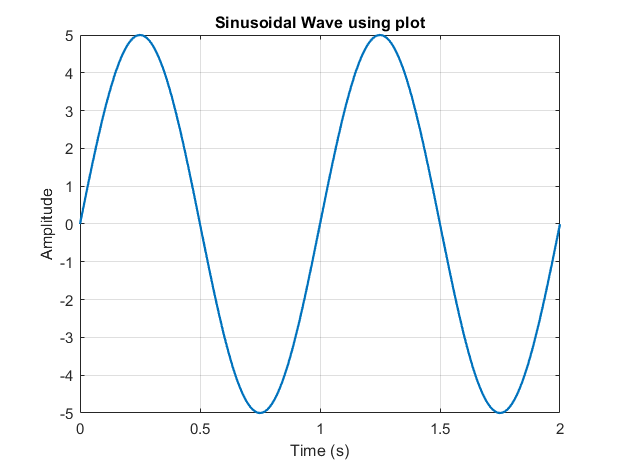


t = 0:0.01:2;
A = 5;
f = 1;
phi = 0;
signal = A*sin(2*pi*f*t + phi);
figure('Name', 'Continuous-Time Sinusoidal Wave');
plot(t, signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoidal Wave using plot');
grid on;

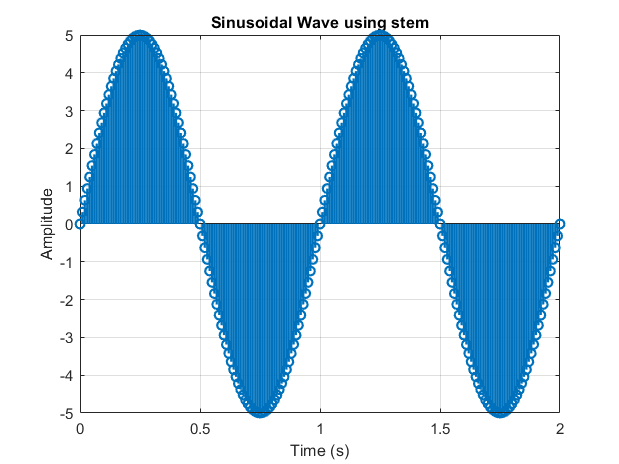

% ---------------------------------------
figure('Name', 'Continuous-Time Sinusoidal Wave');
stem(t, signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoidal Wave using stem');
grid on;

**Section 1-2**

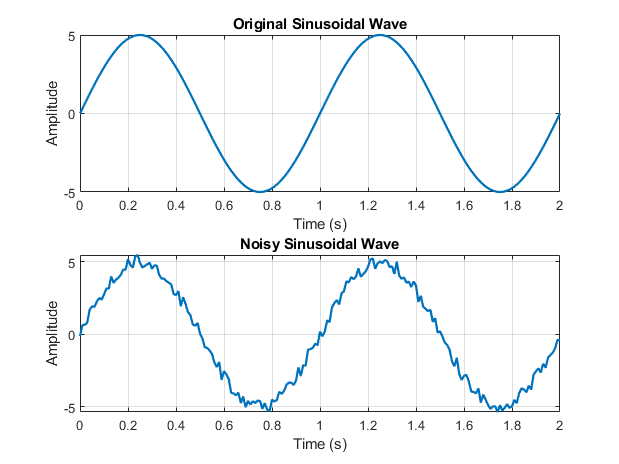


rand_num = rand(1,length(t)) - 0.5;
rand_signal = rand_num + signal;
figure('Name', 'Random Signal');
subplot(211)
plot(t, signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Sinusoidal Wave');
grid on;
subplot(212)
plot(t, rand_signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy Sinusoidal Wave');
grid on;

**Section 1-3**

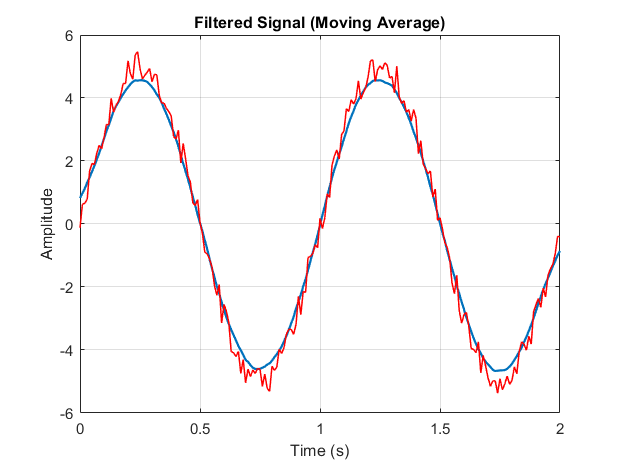

M1 = 0;
M2 = 20;
window_size = M1 + M2 + 1;

kernel = ones(1, window_size) / window_size;
filtered_signal = conv(rand_signal,kernel, "same");

figure('Name', 'Moving Average');
plot(t, filtered_signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Moving Average)');
grid on;
hold on;
plot(t, rand_signal, 'LineWidth', 1,'Color','r');

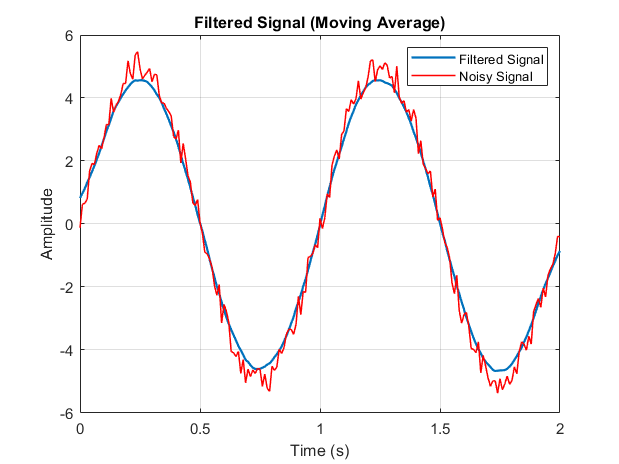


% ???????????????????
M1 = 10;
M2 = 10;
window_size = M1 + M2 + 1;
kernel = ones(1, window_size) / window_size;
filtered_signal = conv(rand_signal, kernel, "same");

figure('Name', 'Moving Average Filtered Signal');
plot(t, filtered_signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Moving Average)');
grid on;
hold on;
plot(t, rand_signal, 'LineWidth', 1, 'Color', 'r');
legend('Filtered Signal', 'Noisy Signal');

**Section 1-4**

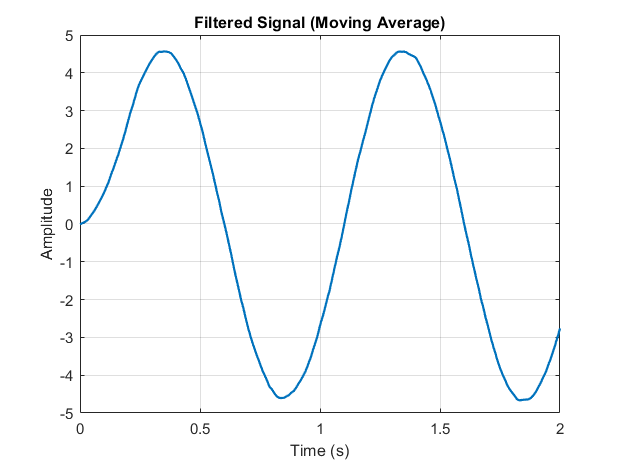

M1 = 0;
M2 = 20;
window_size = M1 + M2 + 1;

% Define the moving average filter coefficients
kernel = ones(1, window_size) / window_size;

% Apply the moving average filter using the 'filter' function
filtered_signal = filter(kernel, 1, rand_signal);

% Plot the results
figure('Name', 'Moving Average');
plot(t, filtered_signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Moving Average)');
grid on;

**section 1-5**

function x = singen(omega0, n)
 
    a = [1, -2*cos(omega0), 1];  
    b = [sin(omega0), 0, 0];  
   
    u = [1, zeros(1, n-1)];   
    x = filter(b, a, u);
    figure;
    stem(0:n-1, x, 'LineWidth', 1.5);
    xlabel('n');
    ylabel('x[n]');
    title(['Generated Sinusoidal Sequence with \omega_0 = ', num2str(omega0)]);
    grid on;
end
